# Isosurface Viewer Widget

`IsosurfaceViewer` is intended for displaying a 3D isosurface.

## Load in data (MRI)

s = load('mri.mat');
data = squeeze(s.D);

% Create isosurface
isovalue = 40;
[faces, vertices] = isosurface(data, isovalue);
voxel_size  = [1 1 3];
vertices    = vertices .* voxel_size;
vertexNormals = isonormals(data,vertices);

% Place into an IsosurfaceModel
isoModel = wt.model.IsosurfaceModel(...
    'Faces',faces,...
    'Vertices',vertices,...
    'VertexNormals',vertexNormals);

## Create the widget

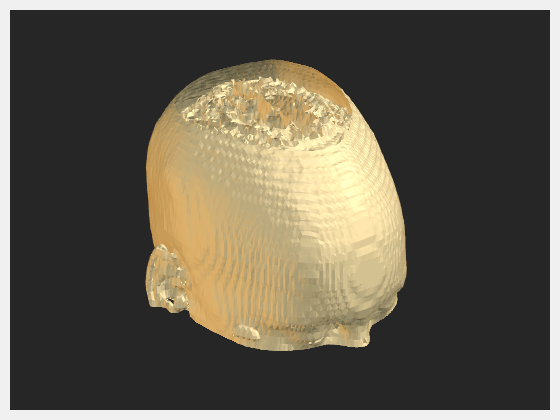

f = uifigure;
g = uigridlayout(f,[1 1]);
w = wt.IsosurfaceViewer(g);
w.IsosurfaceModel = isoModel;

## Load another dataset

Load the raw 3D volume matrix:

imagePath = fullfile(matlabroot,"toolbox","images","imdata",...
    "BrainMRILabeled","images","vol_001.mat");
s = load(imagePath);
data = s.vol;

Create an isosurface:

isovalue = 40;
[faces, vertices] = isosurface(data, isovalue);
voxel_size  = [1 1 3];
vertices    = vertices .* voxel_size;
vertexNormals = isonormals(data,vertices);


Place into an IsosurfaceModel:

isoModel = wt.model.IsosurfaceModel(...
    'Faces',faces,...
    'Vertices',vertices,...
    'VertexNormals',vertexNormals);

Load the data into the viewer:

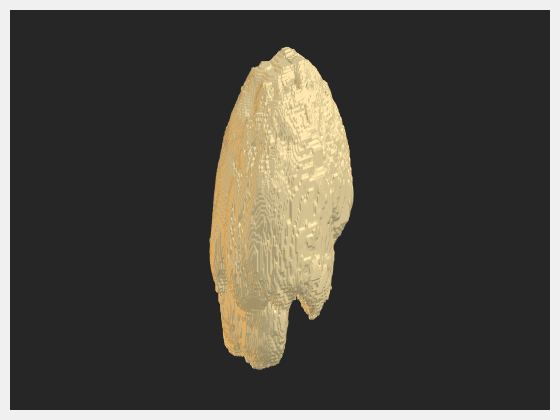

w.IsosurfaceModel = isoModel;

*Copyright 2018-2021 The MathWorks, Inc.*